clear;close all;clc;

## Load image

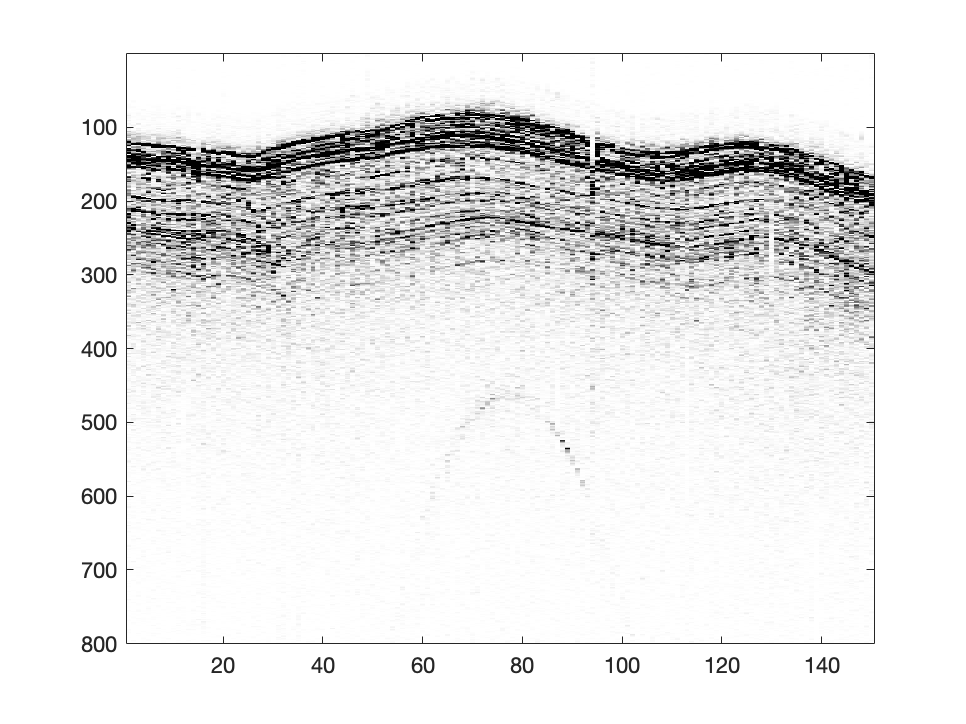

load('case_img.mat')

contrast=4234;

imagesc(img,[0,contrast]),colormap(gca,flipud(gray));

## Pre-processing

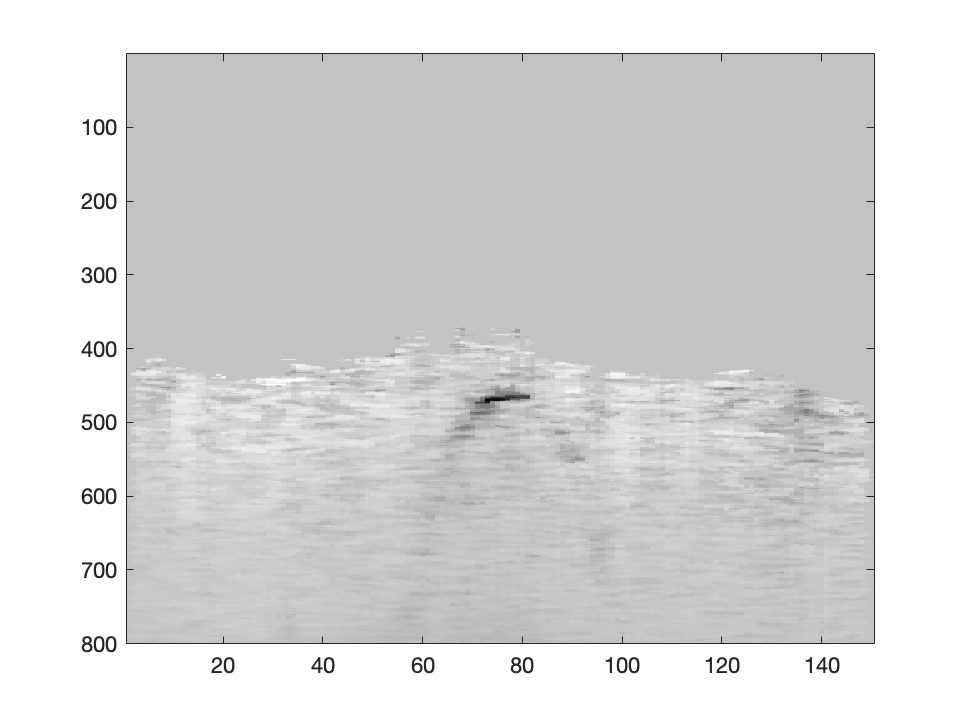

[top_strata,btm_strata] = hori_pick(img,7,0);

[data_ahe,data_edge_ahe,flat] = attenu_SE_v1(img,0.95,280);

data_mid = medfilt2(data_ahe, [5, 5]);

imagesc(data_mid),colormap(gca,flipud(gray));

## Segmentation

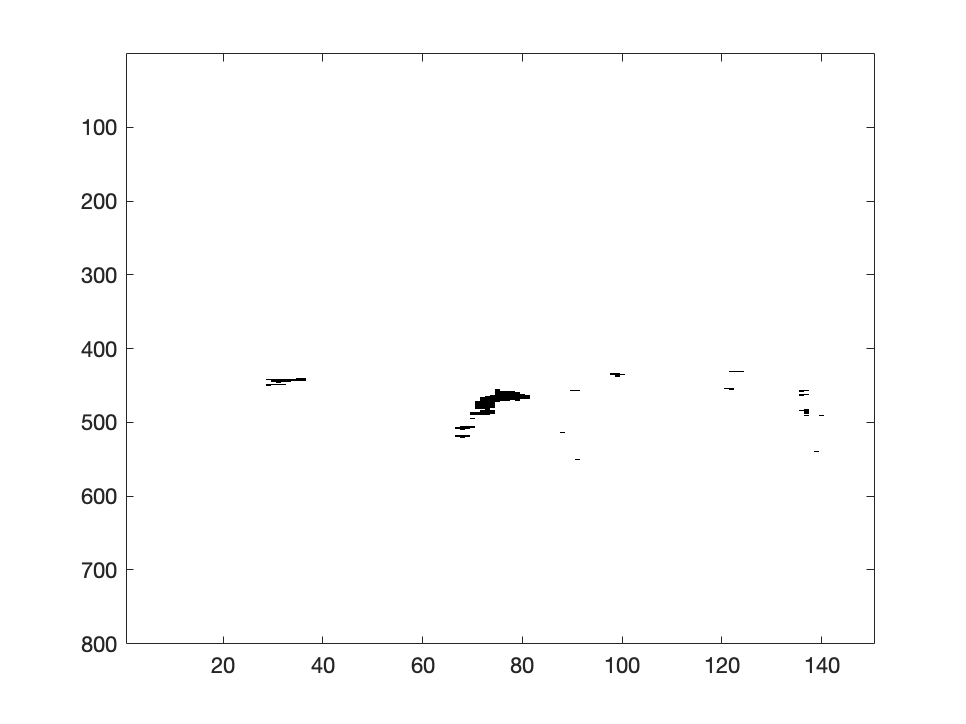

thres=90;
BW1 = grayconnected(data_mid,1,1,thres);
BW1 = imcomplement(BW1);

imagesc(BW1),colormap(gca,flipud(gray));

## Mor-opening

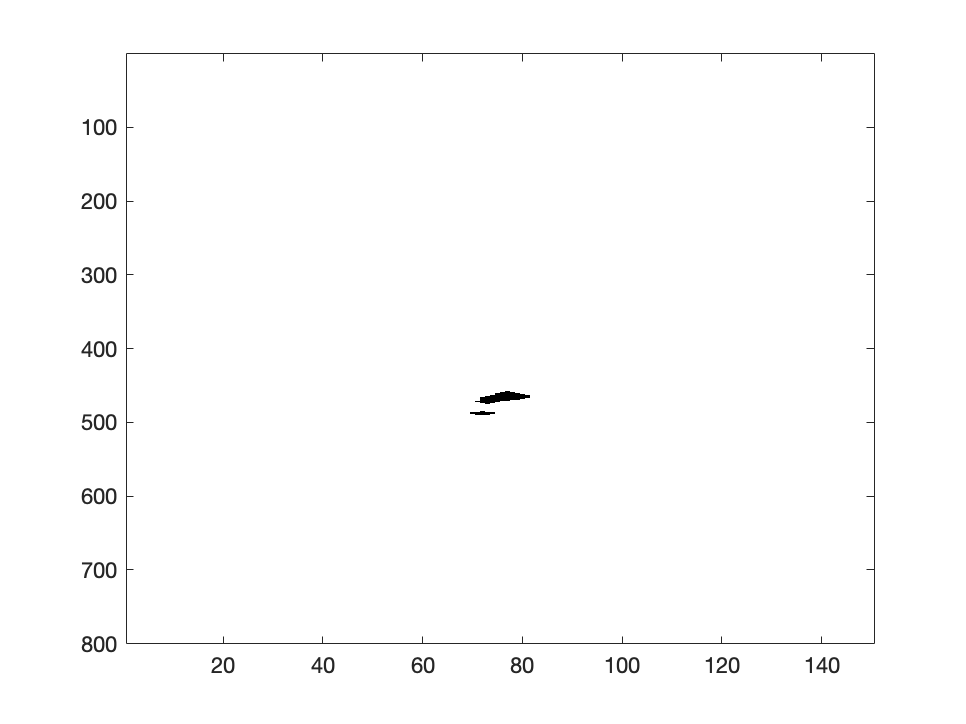

radius = 2;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW2 = imopen(BW1, se);

imagesc(BW2),colormap(gca,flipud(gray));

## Mor-dilation

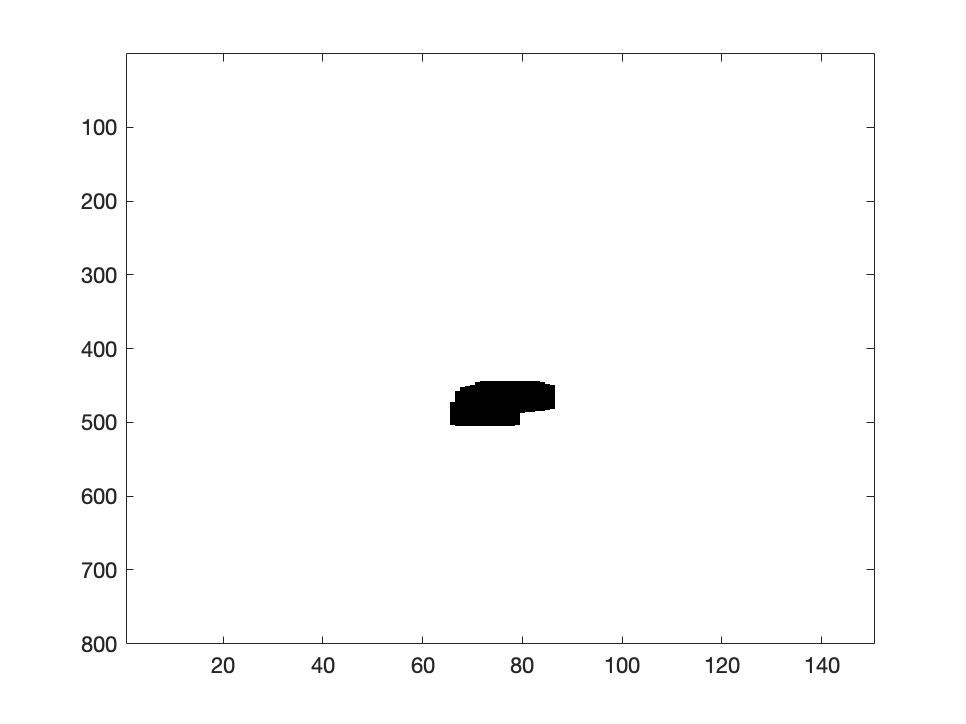

A_rec =30;
B_rec =10;

dimensions = [A_rec B_rec];
se = strel('rectangle', dimensions);
BW3 = imdilate(BW2, se);

figure,
imagesc(BW3),colormap(gca,flipud(gray));

## Mor-skeletonization

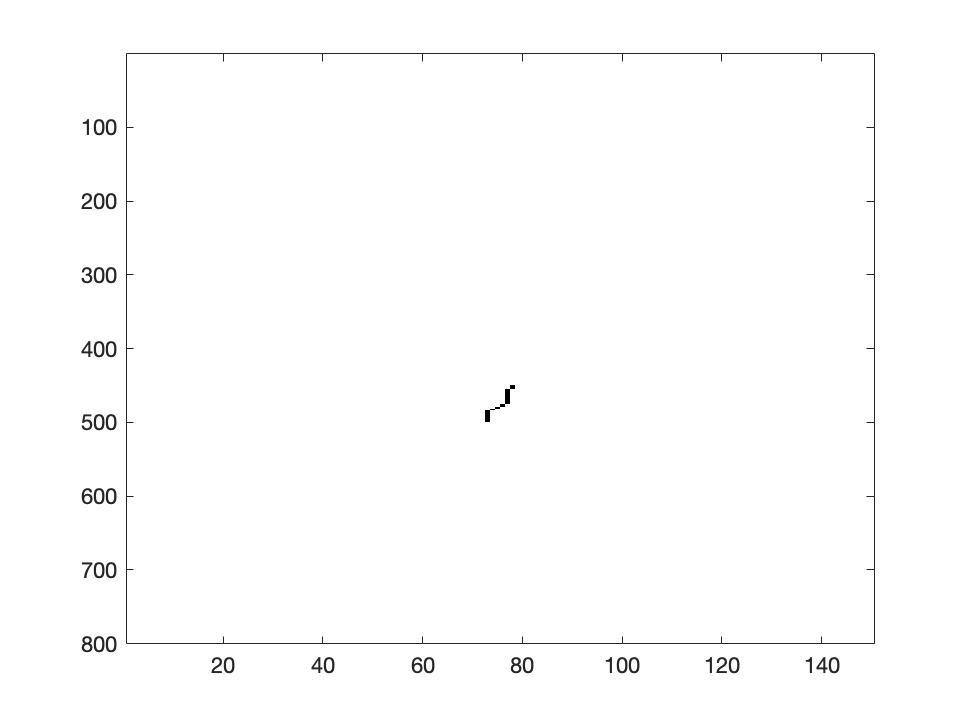

out = bwskel(BW3);

figure,
imagesc(out),colormap(gca,flipud(gray));

## Data-fitting

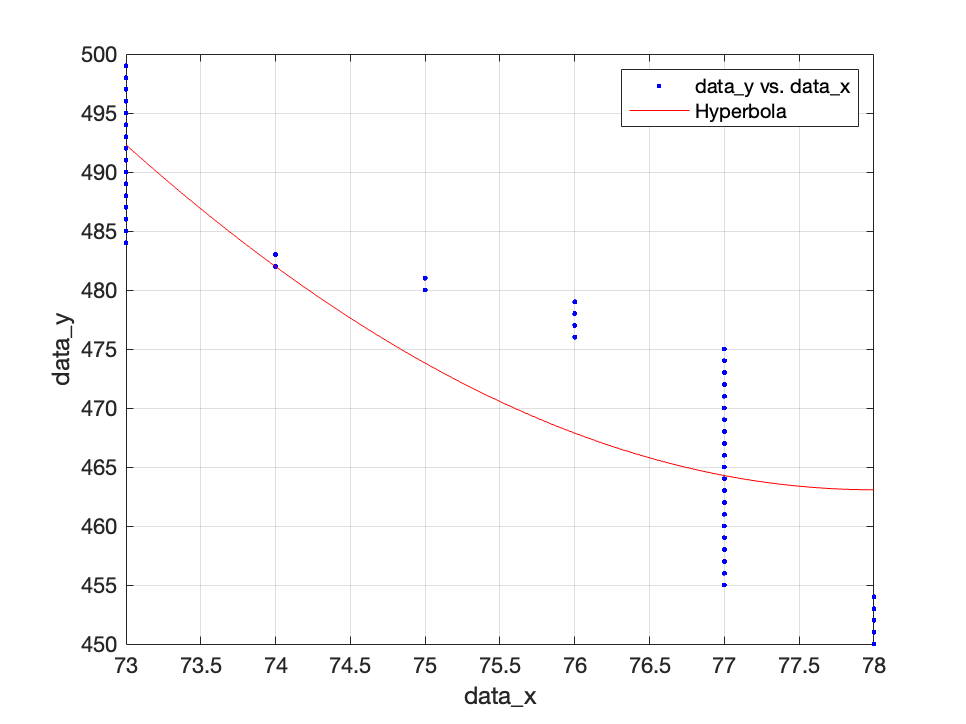

fit_candi = regionprops(out,'PixelList');
line_pixel = fit_candi(1).PixelList;

data_x = line_pixel(:,1);
data_y = line_pixel(:,2);

x0 = max(data_x);

fitresult = curve_fitting(data_x, data_y,x0);

## Result

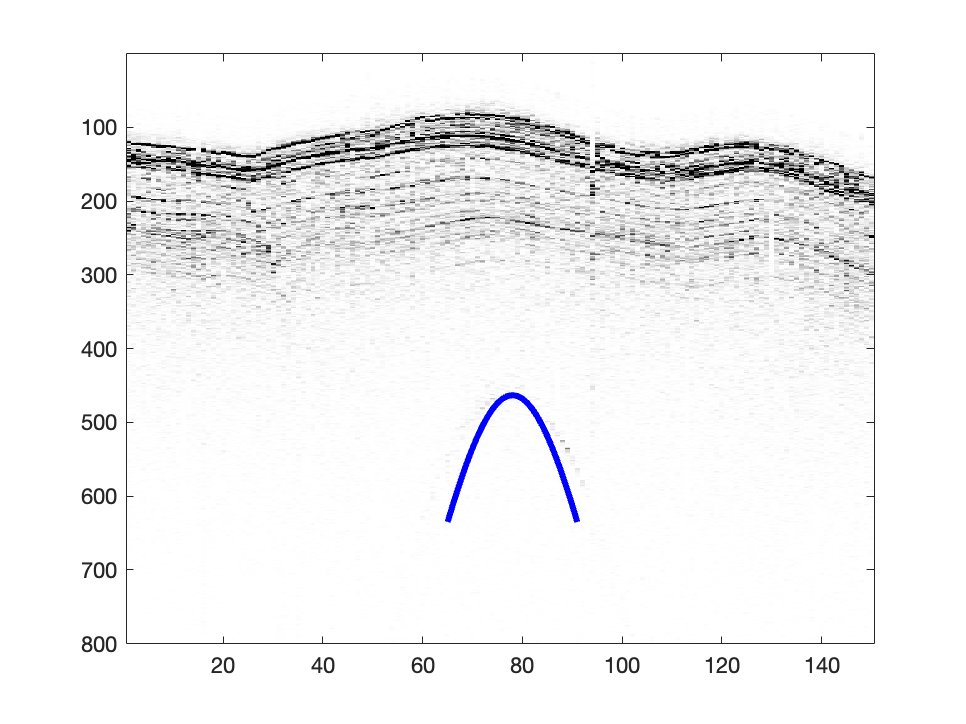

figure,
imagesc(img,[0 10000]),colormap(gca,flipud(gray));

hold on,
a = fitresult.a;
b = fitresult.b;

elem = regionprops(BW3,'BoundingBox');
lb=floor(elem.BoundingBox(1));
rb=lb+(x0-lb)*2;

x1 = lb:1:rb;
y1 = sqrt(a^2*(1+((x1-x0).^2)/b));

plot(x1, y1, 'b-', 'linewidth', 3);